# `while` Loops 

## for Loop vs. while Loop

The usual explanation for the difference between a for loop and a while loop is, "A for loop executes a block of code a fixed number of times; a while loop executes a block of code a variable number of times depending on conditions."Anything that can be done with a for loop can be done with a while loop, and vice-versa.

## Syntax of a while Loop

- The conditional statement must have at least one variable. 

- Variables must be initialized before the loop.

- All counters and variables must be manually incremented. 

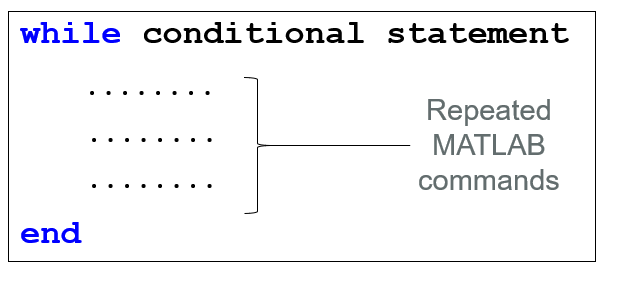

%Example:

x = 1;
while x < 5
	x
	x = x + 1;
end

x = 1

x = 2

x = 3

x = 4

## Infinite Loop - Attention!

If the condition for running the while loop is always true, the loop will run infinitely (i.e **while** 1). 

Use CTRL + C to force MATLAB to break out of the loop! 

%Same example as before, but a very common mistake is forgetting to
%increment the variable. In this case x is always 1 and the loop never
%stops. 

x = 5;
while x < 5
	
	%x = x + 1;
end

## Demo 1 - Try it yourself

Ask the user to input a positive number. Using a while loop check that the number is positive; if not, keep asking for a number until it is positive. Then, display the final number. 

% add your code here
while (true)
    userInput = input("Input a positive number: ");
    fprintf("%i\n", userInput)
    if (userInput > 0)
        break;
        
    end
end

-1
-2
3


## `tic` and `toc`

`tic and toc are MATLAB built-in functions that monitor elapsed time in a program. tic will start a stopwatch, and toc will return the elapsed time since the last tic. `

%Example: while loop with tic and toc. This example illustrates how it is
%more efficient to perform calculations on data sets using array operations
%than a loop.

x=linspace(0,1,1000000);
tic % start stopwatch
y1 = x.^2; % Calculation of y=x^2 using array math
arrayTime=toc % obtain elapsed time and assign it to variable

arrayTime = 0.0072

tic % restart stopwatch
n=1;
while n <= length(x)
y2(n) = x(n)^2; % The same calculation using a loop
n=n+1;
end
loopTime=toc % obtain elapsed time and assign it to variable

loopTime = 0.1136

## Flags

Flags are variables used to mark or reference a certain state or criteria. In many cases it is a true/false variable. It can be used to determine which commands to run next. 

SDP Hint: Flags are ver useful for tracking the current state of a game.

%Example: Guess the number game

theNumber = randi(100);  %generate a random number between 1 and 100
guess = 0;  %initialize the guess to 0


%keep guessing until you get it right
while guess ~= theNumber
    guess = input('Guess a number between 1 and 100: ');

    if  guess>theNumber
        
        %using this instead of fprintf because if works better with live scripts
        msgbox('Too high. Guess again.')

        
    elseif guess<theNumber
                msgbox('Too low. Guess again.')

    else  %must be equal
           msgbox('Correct!')

    end

end



## You try it - while loop

## Another version that imposes a maximum on the number of guesses

num_guesses = 1

num_guesses = 2

num_guesses = 3

num_guesses = 4

num_guesses = 5

num_guesses = 6

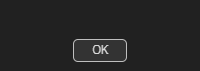

%Guess the number game

%Add a maximum number of guesses

max_guesses = 6;
theNumber = randi(100);  %generate a random number between 1 and 100
guess = 0;  %initialize the guess to 0
%add a variable to keep track of how many guesses have been tried
num_guesses = 0;
%modify the condition so that it times out if the max number of guesses is reached
while guess ~= theNumber
    if num_guesses ~= max_guesses
        guess = input('Guess a number between 1 and 100: ');
        %increment the number of guesses here
        if  guess>theNumber
            msgbox('Too high. Guess again.')
            num_guesses = num_guesses + 1
            
        elseif guess<theNumber
                    msgbox('Too low. Guess again.')
            num_guesses = num_guesses + 1
        else  %must be equal
               msgbox('Correct!')
        end
    else
        msgbox("You ran out of guesses! Goodbye!")
        break;
    end
end


%After the program exits the loop, check to see if the max number of guesses was exceeded
%if so, print 'You lose.' Otherwise, print 'You win!')


